
[a1,b1,c1]=size(AE);
[a2,b2,c2]=size(BN);
[a3,b3,c3]=size(EN);
[a4,b4,c4]=size(DEN);

x1=find(AE>9.9^37);
AE(x1)=0;
x2=find(BN>9.9^37);
BN(x2)=0;
x3=find(EN>9.9^37);
EN(x3)=0;
x4=find(DEN>9.9^37);
DEN(x4)=0;
% x5=find(DEN==0);
% DEN(x5)=[];

crE=[];
crN=[];
crEN=[];
crDEN=[];
x11=[];
x22=[];
x33=[];
x44=[];
for i=1:c1
    e1=max(max(AE(:,:,i)));
    e2=min(min(AE(:,:,i)));
    if abs(e1)>abs(e2)
        crE=[crE, e1];
    else
        crE=[crE, e2];
    end
end
for j=1:c2
    n1=max(max(BN(:,:,j)));
    n2=min(min(BN(:,:,j)));
    if abs(n1)>abs(n2)
        crN=[crN, n1];
    else
        crN=[crN, n2];
    end
end
for j=1:c3
    n1=max(max(EN(:,:,j)));
    crEN=[crEN, n1];
end
for j=1:c4
    n1=mode(mode(DEN(:,:,j)));
    crDEN=[crDEN, n1];
end

Ecr = roundn(crE,-2);
tbl1 = tabulate(Ecr);%统计数组x中元素出现的频率
t1 = array2table(tbl1, 'VariableNames', ...
    {'Value','Count','Percent'});%将数组转化为表
Ncr = roundn(crN,-2);
tbl2 = tabulate(Ncr);%统计数组x中元素出现的频率
t2 = array2table(tbl2, 'VariableNames', ...
    {'Value','Count','Percent'});%将数组转化为表
ENcr = roundn(crEN,-2);
tbl3 = tabulate(ENcr);%统计数组x中元素出现的频率
t3 = array2table(tbl3, 'VariableNames', ...
    {'Value','Count','Percent'});%将数组转化为表
DENcr = roundn(crDEN,-2);
tbl4 = tabulate(DENcr);%统计数组x中元素出现的频率
t4 = array2table(tbl4, 'VariableNames', ...
    {'Value','Count','Percent'});%将数组转化为表

figure()
% subplot(221)
% bar(t1.Value,t1.Count);
% xlabel("Velocity(m/s)");
% ylabel("Count")
% title("Eastward maximum velocity of current monthly")
% 
% subplot(222)
% bar(t2.Value,t2.Count);
% xlabel("Velocity(m/s)");
% ylabel("Count")
% title("Northward maximum velocity of current monthly")

subplot(121)
bar(t3.Value,t3.Count);
xlabel("Velocity (m/s)");
ylabel("Count")
title("Max compound velocity of current")

% subplot(224)
% bar(t4.Value,t4.Count);
% xlabel("Direction(rad)");
% ylabel("Count")
% title("Mode of current direction")


% figure()
subplot(122)
[f,xi]=ksdensity(crEN);
plot(xi,f,'r*');
hold on
[mu,sigma]= normfit(crEN,0.05)

mu = 0.2526

sigma = 0.1113

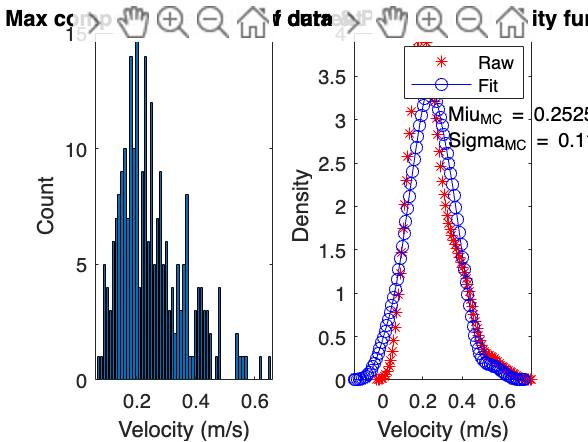

% [mu,sigma,muci,sigmaci]= normfit(data,a);
% data: 原数据
% a :置信度
% mu: 均值
% sigma: 标准差
% muci:1-a 区间内的均值
% sigmaci:1-a 区间内的标准差
TJ=ones(100,1);
LTJ=length(TJ);
N0=normrnd(mu,sigma,1,LTJ);
[f1,xi1]=ksdensity(N0);
plot(xi1,f1,'b-o');
hold off

xlabel('Velocity (m/s)')
ylabel('Density')
legend('Raw','Fit')
title("Raw data & Probability density function")
txt = { ['Miu_{MC} = ' num2str(mu)]; ['Sigma_{MC} = ' num2str(sigma)] };
text(xi(45),f(45)+0.9,txt)